**Task 1**

Afull = full(A);
Bfull = full(B);
Cfull = full(C);

r = 8;
numPairs = r/2;

%% Version 1: initial manual interpolation points
sigma_v1 = [
    0.2000 + 5.0000i
    0.2000 + 8.0000i
    0.2000 + 11.0000i
    0.2000 + 14.0000i
];

showMomentChoice('Version 1: manual initial choice', ...
    sigma_v1, Afull, Bfull, Cfull);


Version 1: manual initial choice
Interpolation points:
   0.2000 + 5.0000i
   0.2000 - 5.0000i
   0.2000 + 8.0000i
   0.2000 - 8.0000i
   0.2000 +11.0000i
   0.2000 -11.0000i
   0.2000 +14.0000i
   0.2000 -14.0000i

S =
    0.2000    5.0000         0         0         0         0         0         0
   -5.0000    0.2000         0         0         0         0         0         0
         0         0    0.2000    8.0000         0         0         0         0
         0         0   -8.0000    0.2000         0         0         0         0
         0         0         0         0    0.2000   11.0000         0         0
         0         0         0         0  -11.0000    0.2000         0         0
         0         0         0         0         0         0    0.2000   14.0000
         0         0         0         0         0         0  -14.0000    0.2000

L =
     1     0     1     0     1     0     1     0

Matched moments C*Pi =
    0.0024    0.0018    0.0004   -0.0007    0.0002   



%% Version 2: interpolation points from frequency response peaks
w = linspace(0.1, 20, 2000);
Hmag = zeros(size(w));

for k = 1:length(w)
    Hmag(k) = abs(Cfull*((1i*w(k)*eye(size(Afull))-Afull)\Bfull));
end

peakIdx = find(Hmag(2:end-1) > Hmag(1:end-2) & ...
               Hmag(2:end-1) >= Hmag(3:end)) + 1;

[~, peakOrder] = sort(Hmag(peakIdx), 'descend');
peakFreq = sort(w(peakIdx(peakOrder(1:numPairs))));

sigma_v2 = 0.2 + 1i*peakFreq(:);

showMomentChoice('Version 2: frequency-response based choice', ...
    sigma_v2, Afull, Bfull, Cfull);


Version 2: frequency-response based choice
Interpolation points:
   0.2000 + 5.2069i
   0.2000 - 5.2069i
   0.2000 + 5.9336i
   0.2000 - 5.9336i
   0.2000 +13.4695i
   0.2000 -13.4695i
   0.2000 +14.2858i
   0.2000 -14.2858i

S =
    0.2000    5.2069         0         0         0         0         0         0
   -5.2069    0.2000         0         0         0         0         0         0
         0         0    0.2000    5.9336         0         0         0         0
         0         0   -5.9336    0.2000         0         0         0         0
         0         0         0         0    0.2000   13.4695         0         0
         0         0         0         0  -13.4695    0.2000         0         0
         0         0         0         0         0         0    0.2000   14.2858
         0         0         0         0         0         0  -14.2858    0.2000

L =
     1     0     1     0     1     0     1     0

Matched moments C*Pi =
    0.0031    0.0009    0.0022   -0.0012   



%% Version 3: interpolation points from system poles
[V, D] = eig(Afull);
lambda = diag(D);

idx = find(real(lambda) < 0 & imag(lambda) > 0);
[~, orderFreq] = sort(imag(lambda(idx)), 'ascend');

selectedPoles_v3 = lambda(idx(orderFreq(1:numPairs)));
sigma_v3 = -conj(selectedPoles_v3);

showMomentChoice('Version 3: pole-based moment matching choice', ...
    sigma_v3, Afull, Bfull, Cfull);


Version 3: pole-based moment matching choice
Interpolation points:
   0.2618 + 5.2299i
   0.2618 - 5.2299i
   0.2657 + 5.8923i
   0.2657 - 5.8923i
   0.2781 + 7.6369i
   0.2781 - 7.6369i
   0.3431 +13.4790i
   0.3431 -13.4790i

S =
    0.2618    5.2299         0         0         0         0         0         0
   -5.2299    0.2618         0         0         0         0         0         0
         0         0    0.2657    5.8923         0         0         0         0
         0         0   -5.8923    0.2657         0         0         0         0
         0         0         0         0    0.2781    7.6369         0         0
         0         0         0         0   -7.6369    0.2781         0         0
         0         0         0         0         0         0    0.3431   13.4790
         0         0         0         0         0         0  -13.4790    0.3431

L =
     1     0     1     0     1     0     1     0

Matched moments C*Pi =
    0.0029    0.0007    0.0021   -0.0010 



%% Version 4: final residue and damping based choice
W = inv(V);

residue = zeros(length(lambda), 1);
for k = 1:length(lambda)
    residue(k) = abs((Cfull*V(:,k)) * (W(k,:)*Bfull));
end

score = residue(idx) ./ max(abs(real(lambda(idx))), 1e-8);
[~, orderFinal] = sort(score, 'descend');

selectedPoles_final = lambda(idx(orderFinal(1:numPairs)));
sigma_final = -conj(selectedPoles_final);

[S, L, Pi, moment, residual] = showMomentChoice( ...
    'Version 4: final moment matching choice', ...
    sigma_final, Afull, Bfull, Cfull);


Version 4: final moment matching choice
Interpolation points:
   0.2618 + 5.2299i
   0.2618 - 5.2299i
   0.3431 +13.4790i
   0.3431 -13.4790i
   0.2657 + 5.8923i
   0.2657 - 5.8923i
   0.3541 +14.2322i
   0.3541 -14.2322i

S =
    0.2618    5.2299         0         0         0         0         0         0
   -5.2299    0.2618         0         0         0         0         0         0
         0         0    0.3431   13.4790         0         0         0         0
         0         0  -13.4790    0.3431         0         0         0         0
         0         0         0         0    0.2657    5.8923         0         0
         0         0         0         0   -5.8923    0.2657         0         0
         0         0         0         0         0         0    0.3541   14.2322
         0         0         0         0         0         0  -14.2322    0.3541

L =
     1     0     1     0     1     0     1     0

Matched moments C*Pi =
    0.0029    0.0007    0.0023    0.0002    0.


disp('Final selected original poles:');

Final selected original poles:


disp(selectedPoles_final);

  -0.2618 + 5.2299i
  -0.3431 +13.4790i
  -0.2657 + 5.8923i
  -0.3541 +14.2322i




disp('Final interpolation points:');

Final interpolation points:


disp(eig(S));

   0.2618 + 5.2299i
   0.2618 - 5.2299i
   0.3431 +13.4790i
   0.3431 -13.4790i
   0.2657 + 5.8923i
   0.2657 - 5.8923i
   0.3541 +14.2322i
   0.3541 -14.2322i




disp('Final S:');

Final S:


disp(S);

    0.2618    5.2299         0         0         0         0         0         0
   -5.2299    0.2618         0         0         0         0         0         0
         0         0    0.3431   13.4790         0         0         0         0
         0         0  -13.4790    0.3431         0         0         0         0
         0         0         0         0    0.2657    5.8923         0         0
         0         0         0         0   -5.8923    0.2657         0         0
         0         0         0         0         0         0    0.3541   14.2322
         0         0         0         0         0         0  -14.2322    0.3541




disp('Final L:');

Final L:


disp(L);

     1     0     1     0     1     0     1     0





%% Local functions
function [S, L, Pi, moment, residual] = showMomentChoice(name, sigmaPairs, A, B, C)

    [S, L] = makeRealSL(sigmaPairs);

    % Moment matching Sylvester equation:
    % A*Pi + B*L = Pi*S
    Pi = sylvester(A, -S, -B*L);

    moment = C*Pi;

    residual = norm(A*Pi + B*L - Pi*S, 'fro') / ...
               max(1, norm(B*L, 'fro'));

    fprintf('\n%s\n', name);
    disp('Interpolation points:');
    disp(eig(S));

    disp('S =');
    disp(S);

    disp('L =');
    disp(L);

    disp('Matched moments C*Pi =');
    disp(moment);

    fprintf('Sylvester residual = %.3e\n', residual);
end

function [S, L] = makeRealSL(sigmaPairs)

    numPairs = length(sigmaPairs);
    r = 2*numPairs;

    S = zeros(r, r);
    L = zeros(1, r);

    for j = 1:numPairs
        sigma = sigmaPairs(j);

        alpha = real(sigma);
        beta = imag(sigma);

        rows = 2*j-1:2*j;

        S(rows, rows) = [alpha, beta; -beta, alpha];
        L(rows) = [1, 0];
    end
end

**Task 2**

%% Task 2: Compute Pi without using sylvester
n = size(Afull, 1);
r = size(S, 1);

%% Compute Pi using Kronecker product
K = kron(eye(r), Afull) - kron(S.', eye(n));
rhs = reshape(-Bfull*L, [], 1);

vecPi = K \ rhs;

Pi_kron = reshape(vecPi, n, r);

%% Check residual of my routine
residual_kron = norm(Afull*Pi_kron + Bfull*L - Pi_kron*S, 'fro') / ...
                max(1, norm(Bfull*L, 'fro'));

%% Compare with MATLAB sylvester
Pi_sylv = sylvester(Afull, -S, -Bfull*L);

residual_sylv = norm(Afull*Pi_sylv + Bfull*L - Pi_sylv*S, 'fro') / ...
                max(1, norm(Bfull*L, 'fro'));

difference = norm(Pi_kron - Pi_sylv, 'fro') / ...
             max(1, norm(Pi_sylv, 'fro'));

%% Display results
disp('Task 2 results');

Task 2 results


fprintf('Residual of my Kronecker routine: %.3e\n', residual_kron);

Residual of my Kronecker routine: 2.792e-16


fprintf('Residual of MATLAB sylvester:     %.3e\n', residual_sylv);

Residual of MATLAB sylvester:     1.647e-14


fprintf('Relative difference:              %.3e\n', difference);

Relative difference:              1.087e-14


**Task 3**

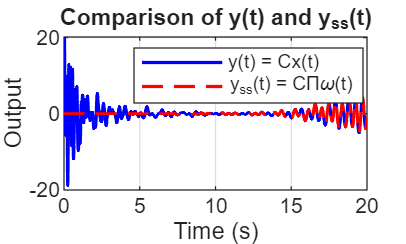

%% Task 3: Output y(t) and steady-state output y_ss(t)
Pi = Pi_kron;

n = size(Afull, 1);
r = size(S, 1);

%% Random initial conditions
rng(1);                  % for reproducibility
x0 = randn(n, 1);
w0 = randn(r, 1);

%% Simulation time
tspan = linspace(0, 20, 3000);

Aaug = [Afull, Bfull*L;
        zeros(r,n), S];

z0 = [x0; w0];

[t, z] = ode45(@(t,z) Aaug*z, tspan, z0);

x = z(:, 1:n).';
w = z(:, n+1:n+r).';

%% Outputs
y = Cfull*x;
y_ss = Cfull*Pi*w;

%% Plot
figure;
plot(t, y, 'b', 'LineWidth', 1.2);
hold on;
plot(t, y_ss, 'r--', 'LineWidth', 1.2);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Comparison of y(t) and y_{ss}(t)');
legend('y(t) = Cx(t)', 'y_{ss}(t) = C\Pi\omega(t)', 'Location', 'best');

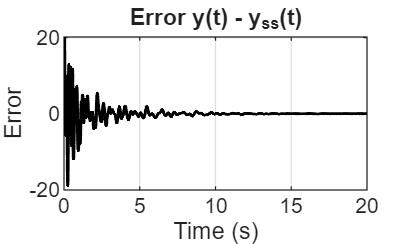


%% Plot error
figure;
plot(t, y - y_ss, 'k', 'LineWidth', 1.2);
grid on;

xlabel('Time (s)');
ylabel('Error');
title('Error y(t) - y_{ss}(t)');


%% Numerical check
initial_error = abs(y(1) - y_ss(1));
final_error = abs(y(end) - y_ss(end));

fprintf('Initial absolute error: %.3e\n', initial_error);

Initial absolute error: 1.858e+00


fprintf('Final absolute error:   %.3e\n', final_error);

Final absolute error:   1.465e-02


**Task 4**

% Force correct vector orientations
Bfull = Bfull(:);       % 48 by 1
Cfull = Cfull(:).';     % 1 by 48
L = L(:).';             % 1 by r

% Use Pi from Task 2
Pi = Pi_kron;

n = size(Afull, 1);
r = size(S, 1);

%% Select desired eigenvalues Sigma for F
Sigma_real = [
   -0.2618
   -0.2618
   -0.3431
   -0.3431
   -0.2657
   -0.2657
   -0.3541
   -0.3541
];

Sigma_imag = [
    5.2299
   -5.2299
   13.4790
  -13.4790
    5.8923
   -5.8923
   14.2322
  -14.2322
];

Sigma = complex(Sigma_real, Sigma_imag);
%% Compute G such that F = S - G*L has eigenvalues Sigma
K = place(S.', L.', Sigma);
G = K.';
G = G(:);               % force G to be r by 1

F = S - G*L;
H = Cfull*Pi;

disp('Eigenvalues of F:');

Eigenvalues of F:


disp(eig(F));

  -0.2618 + 5.2299i
  -0.2618 - 5.2299i
  -0.2657 + 5.8923i
  -0.2657 - 5.8923i
  -0.3541 +14.2322i
  -0.3541 -14.2322i
  -0.3431 +13.4790i
  -0.3431 -13.4790i




%% Check dimensions before building Aaug
disp('Size check:');

Size check:


disp(['Afull: ', mat2str(size(Afull))]);

Afull: [48 48]


disp(['Bfull*L: ', mat2str(size(Bfull*L))]);

Bfull*L: [48 8]


disp(['F: ', mat2str(size(F))]);

F: [8 8]


disp(['G*L: ', mat2str(size(G*L))]);

G*L: [8 8]


disp(['S: ', mat2str(size(S))]);

S: [8 8]


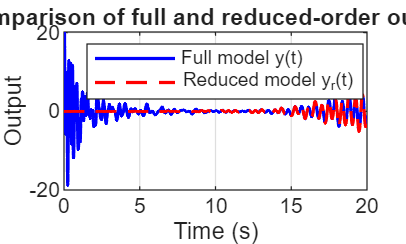


%% Simulate original and reduced systems with same input u = L*w
rng(1);

x0 = randn(n,1);
w0 = randn(r,1);
xi0 = w0;

tspan = linspace(0, 20, 3000);

% Build block matrices separately to avoid dimension mistakes
A11 = Afull;
A12 = zeros(n,r);
A13 = Bfull*L;

A21 = zeros(r,n);
A22 = F;
A23 = G*L;

A31 = zeros(r,n);
A32 = zeros(r,r);
A33 = S;

Aaug = [
    A11, A12, A13;
    A21, A22, A23;
    A31, A32, A33
];

z0 = [x0; xi0; w0];

[t, z] = ode45(@(t,z) Aaug*z, tspan, z0);

x = z(:, 1:n).';
xi = z(:, n+1:n+r).';

y = Cfull*x;
yr = H*xi;

%% Plot
figure;
plot(t, y, 'b', 'LineWidth', 1.2);
hold on;
plot(t, yr, 'r--', 'LineWidth', 1.2);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Comparison of full and reduced-order outputs');
legend('Full model y(t)', 'Reduced model y_r(t)', 'Location', 'best');

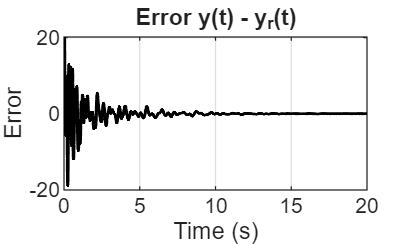


figure;
plot(t, y - yr, 'k', 'LineWidth', 1.2);
grid on;

xlabel('Time (s)');
ylabel('Error');
title('Error y(t) - y_r(t)');


%% Numerical comparison
initial_error = abs(y(1) - yr(1));
final_error = abs(y(end) - yr(end));
relative_error = norm(y - yr) / norm(y);

fprintf('Initial absolute error: %.3e\n', initial_error);

Initial absolute error: 1.858e+00


fprintf('Final absolute error:   %.3e\n', final_error);

Final absolute error:   1.465e-02


fprintf('Relative output error:  %.3e\n', relative_error);

Relative output error:  8.863e-01


**Task 5**

%% Task 5: Bode comparison and improved ROM by tuning S and Sigma
r = 8;
numPairs = r/2;

%% Initial ROM from Task 4
L = [1 0 1 0 1 0 1 0];

sigma_initial = complex( ...
    [0.2618; 0.3431; 0.2657; 0.3541], ...
    [5.2299; 13.4790; 5.8923; 14.2322]);

Sigma_initial = complex( ...
    [-0.2618; -0.2618; -0.3431; -0.3431; -0.2657; -0.2657; -0.3541; -0.3541], ...
    [ 5.2299; -5.2299; 13.4790; -13.4790; 5.8923; -5.8923; 14.2322; -14.2322]);

[S_initial, L] = makeRealSL_task5b(sigma_initial);
[F_initial, G_initial, H_initial, Pi_initial] = buildROM_task5b(Afull, Bfull, Cfull, S_initial, L, Sigma_initial);

%% Improved ROM
importantFreq = [
    5.2299
    5.8923
    13.4790
    14.2322
];

alphaS = 0.25;
alphaF = 0.30;

sigma_improved = complex( ...
    alphaS*ones(numPairs,1), ...
    importantFreq);

Sigma_improved = complex( ...
    [-alphaF; -alphaF; -alphaF; -alphaF; -alphaF; -alphaF; -alphaF; -alphaF], ...
    [ importantFreq(1); -importantFreq(1); ...
      importantFreq(2); -importantFreq(2); ...
      importantFreq(3); -importantFreq(3); ...
      importantFreq(4); -importantFreq(4)]);

[S_improved, L] = makeRealSL_task5b(sigma_improved);
[F_improved, G_improved, H_improved, Pi_improved] = buildROM_task5b(Afull, Bfull, Cfull, S_improved, L, Sigma_improved);

%% Bode comparison
w = logspace(-1, 2, 2000);

G_full_freq = zeros(size(w));
G_initial_freq = zeros(size(w));
G_improved_freq = zeros(size(w));

for k = 1:length(w)
    s = 1i*w(k);

    G_full_freq(k) = Cfull*((s*eye(n) - Afull)\Bfull);
    G_initial_freq(k) = H_initial*((s*eye(size(F_initial)) - F_initial)\G_initial);
    G_improved_freq(k) = H_improved*((s*eye(size(F_improved)) - F_improved)\G_improved);
end

mag_full_db = 20*log10(abs(G_full_freq));
mag_initial_db = 20*log10(abs(G_initial_freq));
mag_improved_db = 20*log10(abs(G_improved_freq));

phase_full = unwrap(angle(G_full_freq))*180/pi;
phase_initial = unwrap(angle(G_initial_freq))*180/pi;
phase_improved = unwrap(angle(G_improved_freq))*180/pi;

err_initial = norm(mag_full_db - mag_initial_db) / norm(mag_full_db);
err_improved = norm(mag_full_db - mag_improved_db) / norm(mag_full_db);

fprintf('Initial Bode magnitude relative error: %.3e\n', err_initial);

Initial Bode magnitude relative error: 6.420e-02


fprintf('Improved Bode magnitude relative error: %.3e\n', err_improved);

Improved Bode magnitude relative error: 6.910e-02



disp('Improved interpolation frequencies:');

Improved interpolation frequencies:


disp(importantFreq);

    5.2299
    5.8923
   13.4790
   14.2322




disp('Improved S:');

Improved S:


disp(S_improved);

    0.2500    5.2299         0         0         0         0         0         0
   -5.2299    0.2500         0         0         0         0         0         0
         0         0    0.2500    5.8923         0         0         0         0
         0         0   -5.8923    0.2500         0         0         0         0
         0         0         0         0    0.2500   13.4790         0         0
         0         0         0         0  -13.4790    0.2500         0         0
         0         0         0         0         0         0    0.2500   14.2322
         0         0         0         0         0         0  -14.2322    0.2500




disp('Improved Sigma:');

Improved Sigma:


disp(Sigma_improved);

  -0.3000 + 5.2299i
  -0.3000 - 5.2299i
  -0.3000 + 5.8923i
  -0.3000 - 5.8923i
  -0.3000 +13.4790i
  -0.3000 -13.4790i
  -0.3000 +14.2322i
  -0.3000 -14.2322i



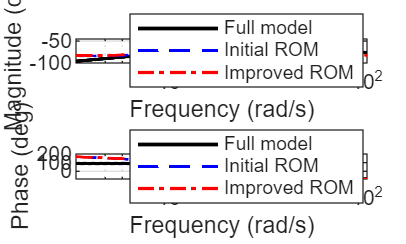


%% Plot Bode magnitude and phase
figure;

subplot(2,1,1);
semilogx(w, mag_full_db, 'k', 'LineWidth', 1.4);
hold on;
semilogx(w, mag_initial_db, 'b--', 'LineWidth', 1.1);
semilogx(w, mag_improved_db, 'r-.', 'LineWidth', 1.2);
grid on;
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Magnitude');
legend('Full model', 'Initial ROM', 'Improved ROM', 'Location', 'best');

subplot(2,1,2);
semilogx(w, phase_full, 'k', 'LineWidth', 1.4);
hold on;
semilogx(w, phase_initial, 'b--', 'LineWidth', 1.1);
semilogx(w, phase_improved, 'r-.', 'LineWidth', 1.2);
grid on;
xlabel('Frequency (rad/s)');
ylabel('Phase (deg)');
title('Bode Phase');
legend('Full model', 'Initial ROM', 'Improved ROM', 'Location', 'best');

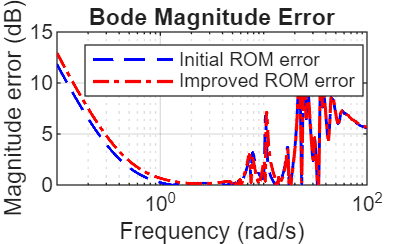


%% Plot magnitude error
figure;
semilogx(w, abs(mag_full_db - mag_initial_db), 'b--', 'LineWidth', 1.1);
hold on;
semilogx(w, abs(mag_full_db - mag_improved_db), 'r-.', 'LineWidth', 1.2);
grid on;
xlabel('Frequency (rad/s)');
ylabel('Magnitude error (dB)');
title('Bode Magnitude Error');
legend('Initial ROM error', 'Improved ROM error', 'Location', 'best');



%% Local functions
function [F, G, H, Pi] = buildROM_task5b(A, B, C, S, L, Sigma)

    n = size(A, 1);
    r = size(S, 1);

    L = L(:).';

    Kpi = kron(eye(r), A) - kron(S.', eye(n));
    rhs = reshape(-B*L, [], 1);
    vecPi = Kpi \ rhs;
    Pi = reshape(vecPi, n, r);

    Kplace = place(S.', L.', Sigma);
    G = Kplace.';
    G = real(G(:));

    F = real(S - G*L);
    H = real(C*Pi);
end

function [S, L] = makeRealSL_task5b(sigmaPairs)

    numPairs = length(sigmaPairs);
    r = 2*numPairs;

    S = zeros(r, r);
    L = zeros(1, r);

    for j = 1:numPairs
        sigma = sigmaPairs(j);

        alpha = real(sigma);
        beta = imag(sigma);

        rows = 2*j-1:2*j;

        S(rows, rows) = [alpha, beta; -beta, alpha];
        L(rows) = [1, 0];
    end
end

**Task 6**

%% Task 6: Data-driven approximation of C*Pi
%% True value for comparison
CPi_true = Cfull * Pi;

%% Generate data using the same S
rng(3);

x0 = randn(n, 1);
w0 = randn(r, 1);

tspan = linspace(0, 20, 4000);

Aaug = [
    Afull, Bfull*L;
    zeros(r,n), S
];

z0 = [x0; w0];

[t, z] = ode45(@(t,z) Aaug*z, tspan, z0);

x = z(:, 1:n).';
omega = z(:, n+1:n+r).';

y = Cfull * x;

%% Use only steady-state data
t_start = 10;
idx = t >= t_start;

Y_data = y(:, idx);
Omega_data = omega(:, idx);

%% Check data richness
rank_Omega = rank(Omega_data);
cond_Omega = cond(Omega_data * Omega_data.');

fprintf('Rank of Omega data matrix: %d\n', rank_Omega);

Rank of Omega data matrix: 8


fprintf('Condition number of Omega*Omega'': %.3e\n', cond_Omega);

Condition number of Omega*Omega': 1.836e+02



%% Data-driven least-squares approximation
CPi_hat = Y_data / Omega_data;

%% Compare with true C*Pi
absolute_error = norm(CPi_hat - CPi_true, 'fro');
relative_error = norm(CPi_hat - CPi_true, 'fro') / norm(CPi_true, 'fro');

fprintf('True C*Pi:\n');

True C*Pi:


disp(CPi_true);

    0.0029    0.0007    0.0023    0.0002    0.0021   -0.0010    0.0017   -0.0011




fprintf('Estimated C*Pi from data:\n');

Estimated C*Pi from data:


disp(CPi_hat);

    0.0027    0.0000    0.0023    0.0002    0.0019   -0.0010    0.0016   -0.0011




fprintf('Absolute error in C*Pi estimate: %.3e\n', absolute_error);

Absolute error in C*Pi estimate: 7.579e-04


fprintf('Relative error in C*Pi estimate: %.3e\n', relative_error);

Relative error in C*Pi estimate: 1.557e-01



%% Reconstruct output using estimated C*Pi
y_hat = CPi_hat * omega;
y_ss_true = CPi_true * omega;

output_fit_error = norm(y(:, idx) - y_hat(:, idx)) / norm(y(:, idx));

fprintf('Relative output fitting error after transient: %.3e\n', output_fit_error);

Relative output fitting error after transient: 7.039e-02


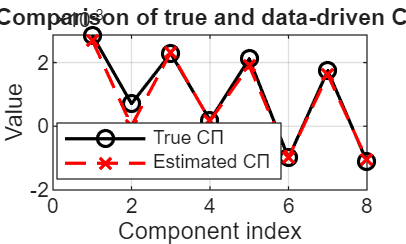


%% Plot true and estimated C*Pi
figure;
plot(1:r, CPi_true, 'ko-', 'LineWidth', 1.2);
hold on;
plot(1:r, CPi_hat, 'rx--', 'LineWidth', 1.2);
grid on;
xlabel('Component index');
ylabel('Value');
title('Comparison of true and data-driven C\Pi');
legend('True C\Pi', 'Estimated C\Pi', 'Location', 'best');

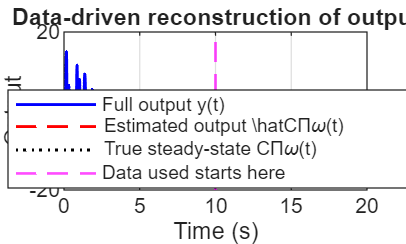


%% Plot output reconstruction
figure;
plot(t, y, 'b', 'LineWidth', 1.1);
hold on;
plot(t, y_hat, 'r--', 'LineWidth', 1.1);
plot(t, y_ss_true, 'k:', 'LineWidth', 1.1);
xline(t_start, 'm--', 'LineWidth', 1.0);
grid on;
xlabel('Time (s)');
ylabel('Output');
title('Data-driven reconstruction of output');
legend('Full output y(t)', 'Estimated output \hat{C\Pi}\omega(t)', ...
       'True steady-state C\Pi\omega(t)', 'Data used starts here', ...
       'Location', 'best');

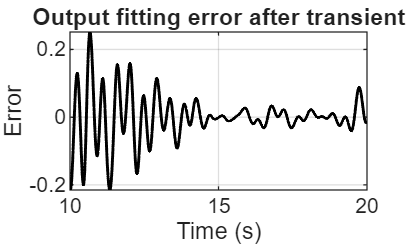


%% Plot fitting error after transient
figure;
plot(t(idx), y(:, idx) - y_hat(:, idx), 'k', 'LineWidth', 1.1);
grid on;
xlabel('Time (s)');
ylabel('Error');
title('Output fitting error after transient');